%% EXE1:
clear all; close all;

%original signal:á
[y,Fs] = audioread("SunshineSquare.wav");

%spectrum analyzies:
L=length(y);
NFFT=2^(nextpow2(L));
Y_FFT=abs(fft(y,NFFT));
Y_FFT1=abs(fftshift(Y_FFT));
f=(Fs).*(0:(NFFT/2-1))/NFFT;
subplot(2,2,1)
plot(f,Y_FFT(1:length(f)));

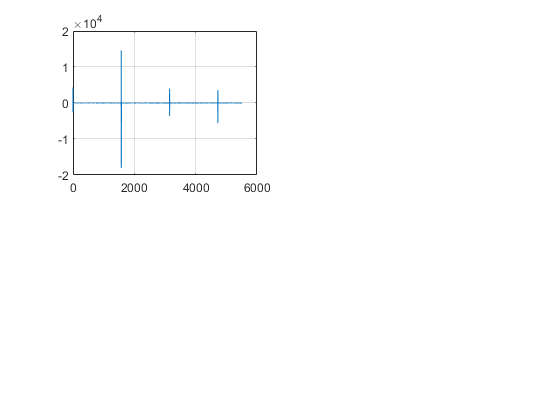

YFFT_2=Y_FFT/max(Y_FFT);
grid;

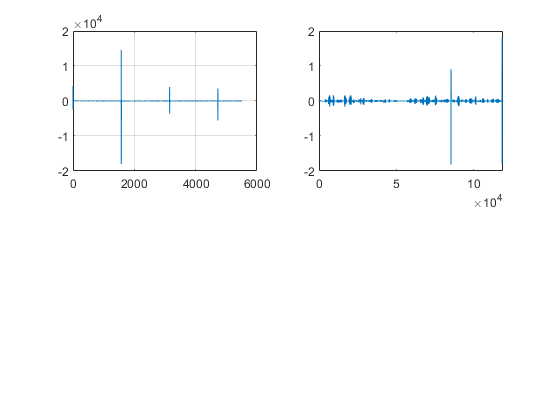

%Filtering:
hn1=[1,-2.0000000000,1];
hn2=[1,-1.246979654,1];
hn3=[1,0.445041864,1];
hn4=[1,1.801937747,1];
hn=conv(hn1,hn2);
hn=conv(hn,hn3);
hn=conv(hn,hn4);
con=conv(y,hn);
confft=abs(fft(con));
subplot(2,2,2);
plot(con)

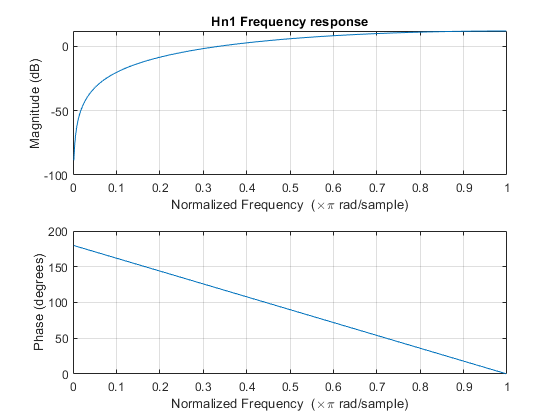

figure(2); freqz(hn1)
title('Hn1 Frequency response')

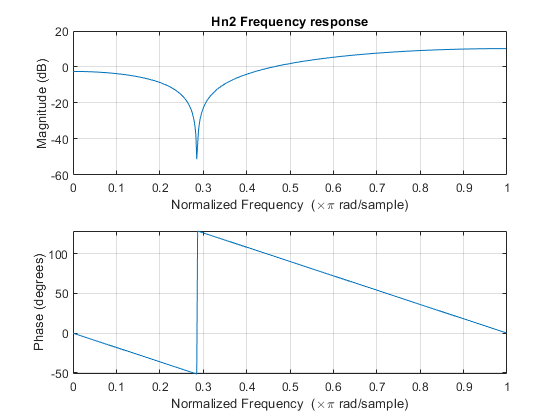

figure(3); freqz(hn2)
title('Hn2 Frequency response')

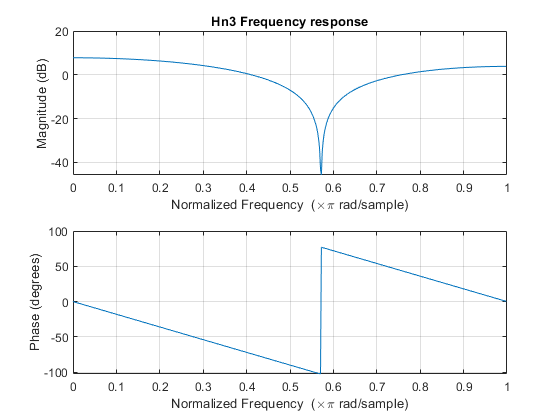

figure(4); freqz(hn3)
title('Hn3 Frequency response')

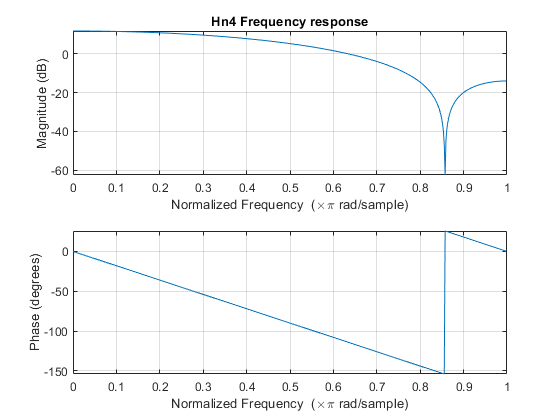

figure(5); freqz(hn4)
title('Hn4 Frequency response')

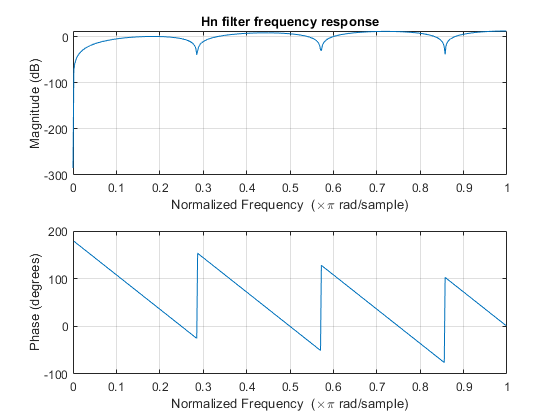

figure(6); freqz(hn);
title('Hn filter frequency response')

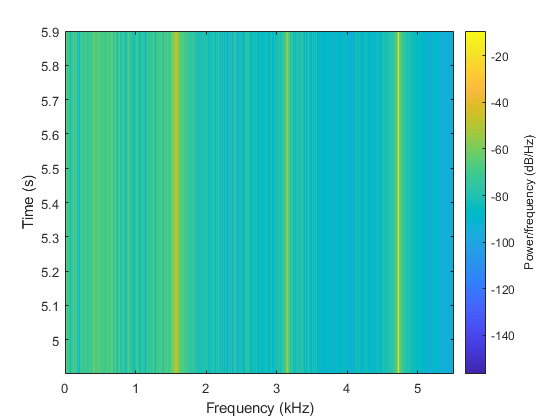

spectrogram(y,L,NFFT/2,NFFT,Fs)

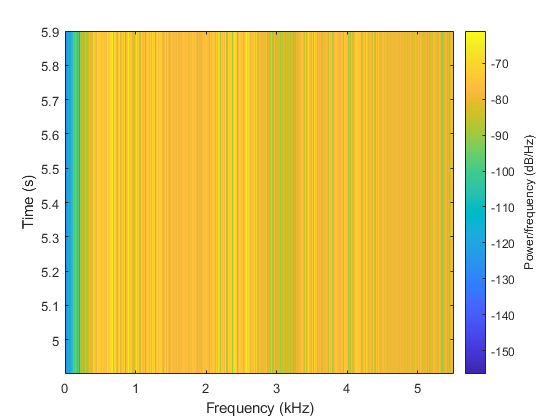

spectrogram(con,L,NFFT/2,NFFT,Fs)